# Gantt Chat Plot Examples

Visualize the start and finish dates of various tasks and activities in a project.

### Plot a Gantt chart given the following data.

Initialize the data below containing various research tasks.

Task = ["Research"
    "Data Collection" 
    "Analysis" 
    "Paper"];

StartDate = [datetime(2022,4,20)
    datetime(2022,4,24)
    datetime(2022,5,1)
    datetime(2022,5,7)];

EndDate = [datetime(2022,4,27) 
    datetime(2022,5,1)
    datetime(2022,5,7)
    datetime(2022,6,1)];

Duration = days([7; 7; 6; 25]);

Deadline = [datetime(2022, 5, 10)
    datetime(2022, 5, 16)
    datetime(2022, 4, 29)
    datetime(2022, 5, 21)];

Plot the Gantt chart using the duration of each research task and label the axes.

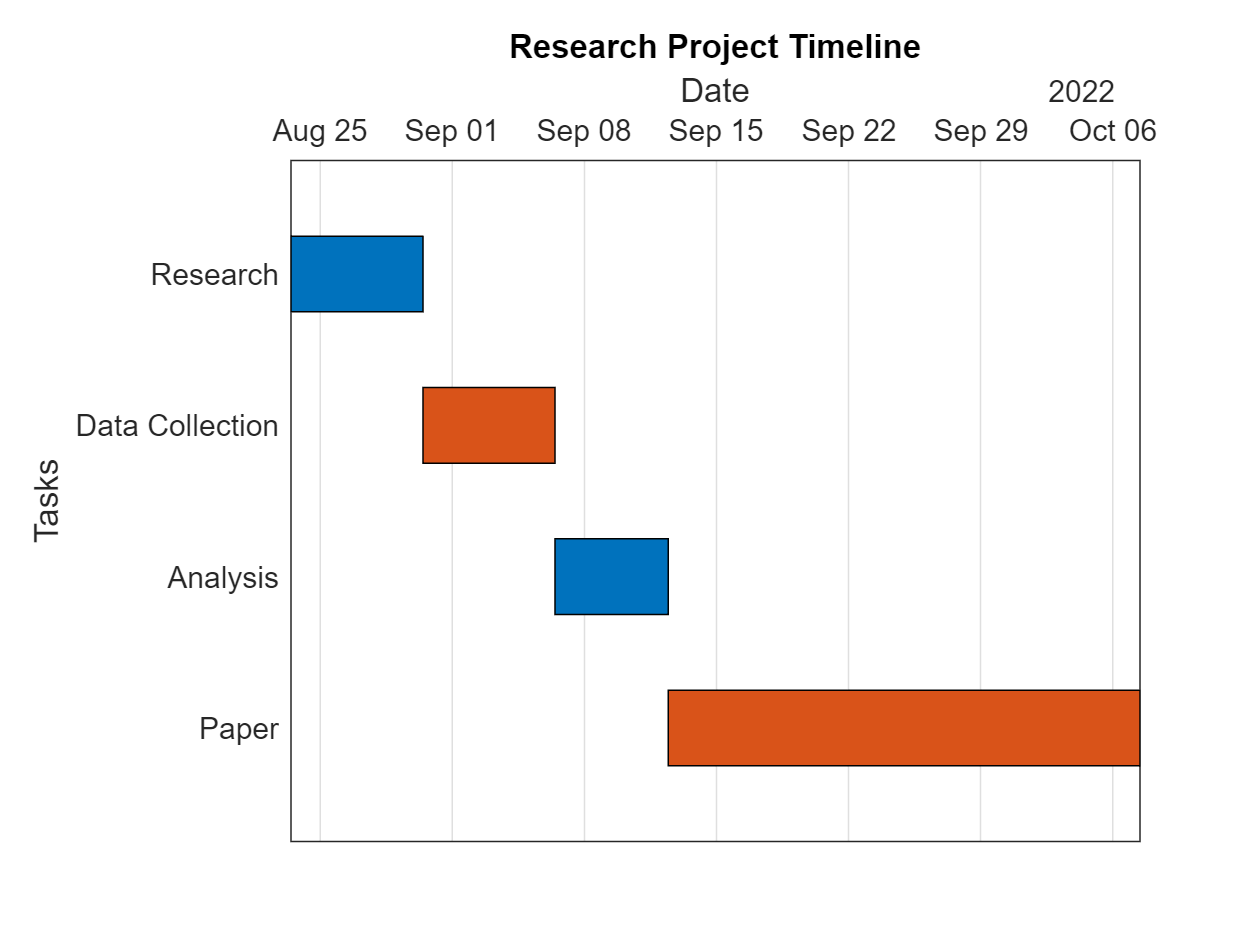

g = ganttChart(Task, Duration);
g.Title = 'Research Project Timeline';
g.TimeAxisLabel = 'Date';
g.TaskAxisLabel = 'Tasks';
g.FaceColor = ['#0072BD'; '#D95319'];

Additionally, we can also plot it using specified start and end dates. Note that the bar colors automatically alternate when multiple colors are passed in.

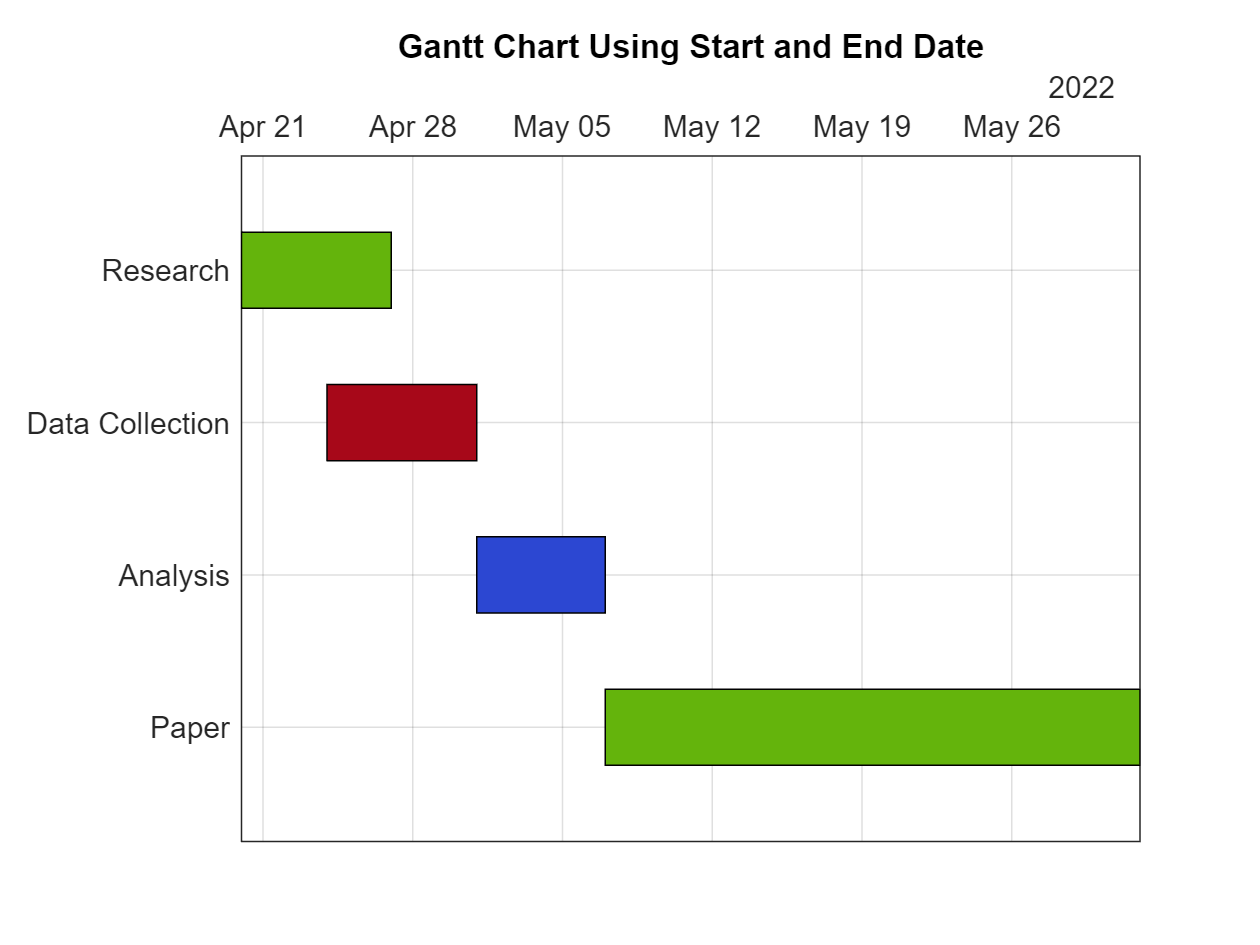

h = ganttChart(Task, StartDate, EndDate);
h.Title = 'Gantt Chart Using Start and End Date';
h.FaceColor = rand(3, 3);
h.Grid = 'on';

Another way we can plot a Gantt chart is using the start date and duration of various tasks. Let's also view the timeline relative to today's date.

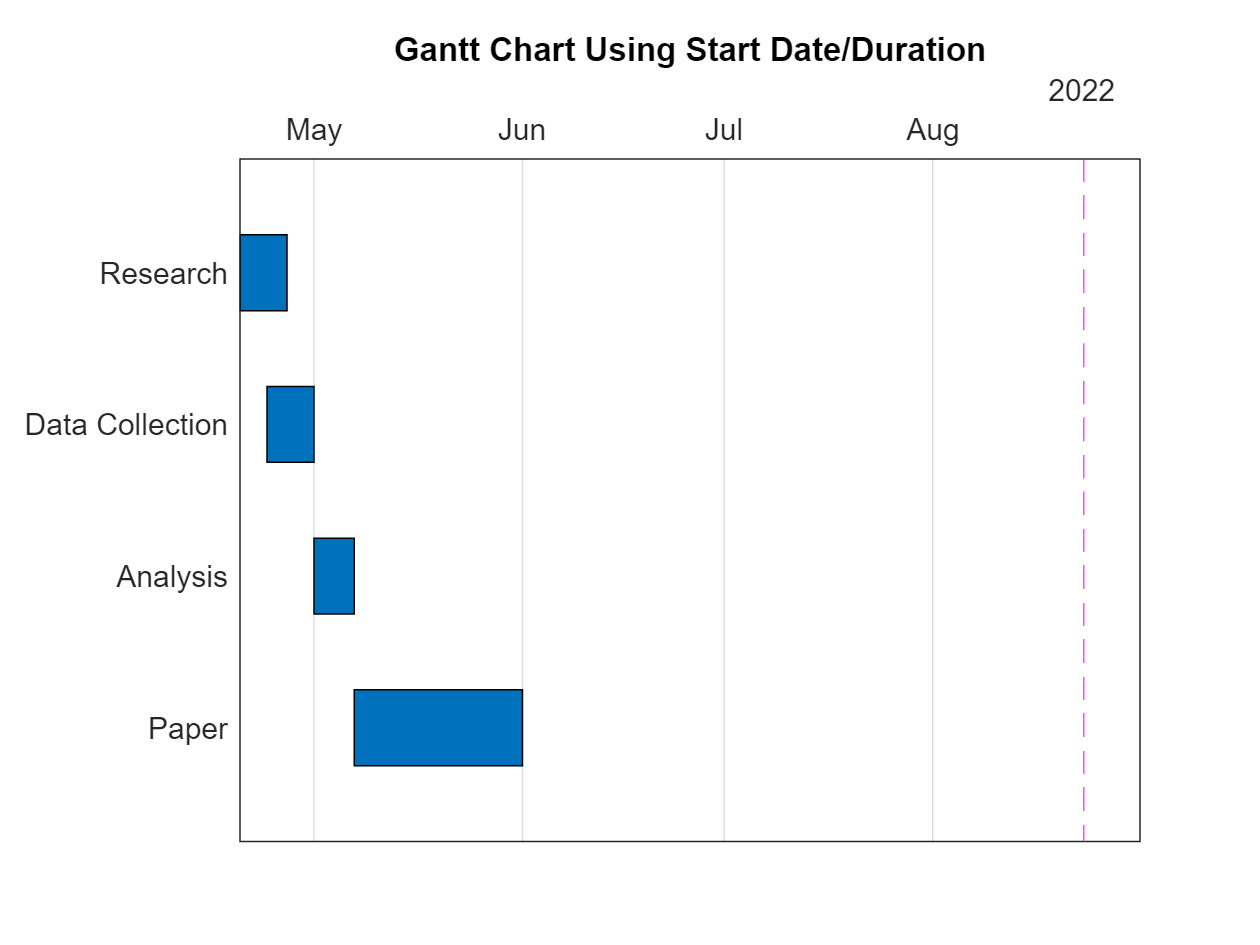

g = ganttChart(Task, StartDate, Duration);
g.Title = 'Gantt Chart Using Start Date/Duration';
g.ShowNowLine = 'on';
g.NowLineColor = 'magenta';

Finally, we can also plot tasks using their respective deadlines (end dates) and time duration. Note the thinner bar width.

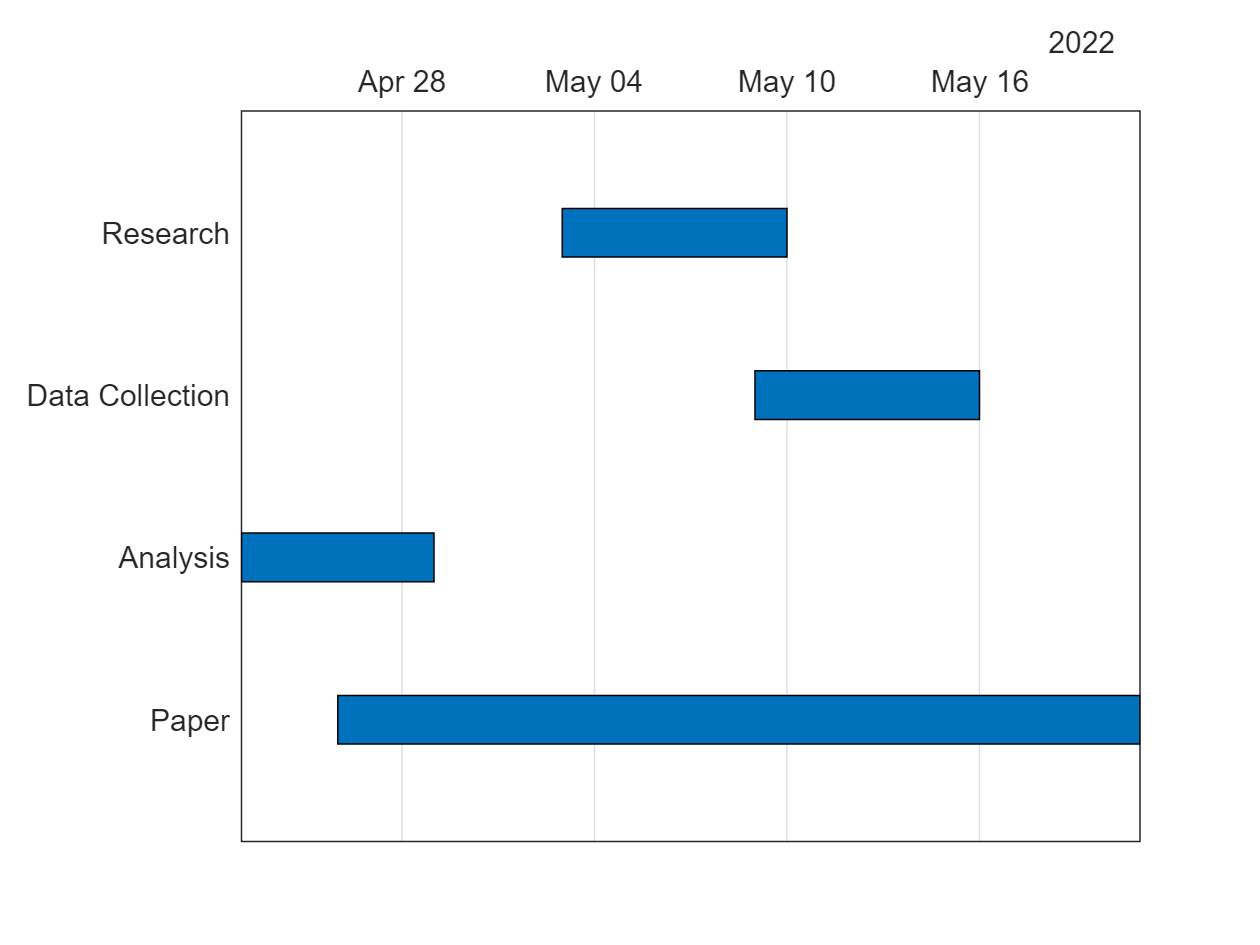

j = ganttChart(Task, Duration, Deadline);
j.BarWidth = 0.3;

Tasks can be sorted by start date as well. The default setting is to sort in ascending order, but descending can also be specified.

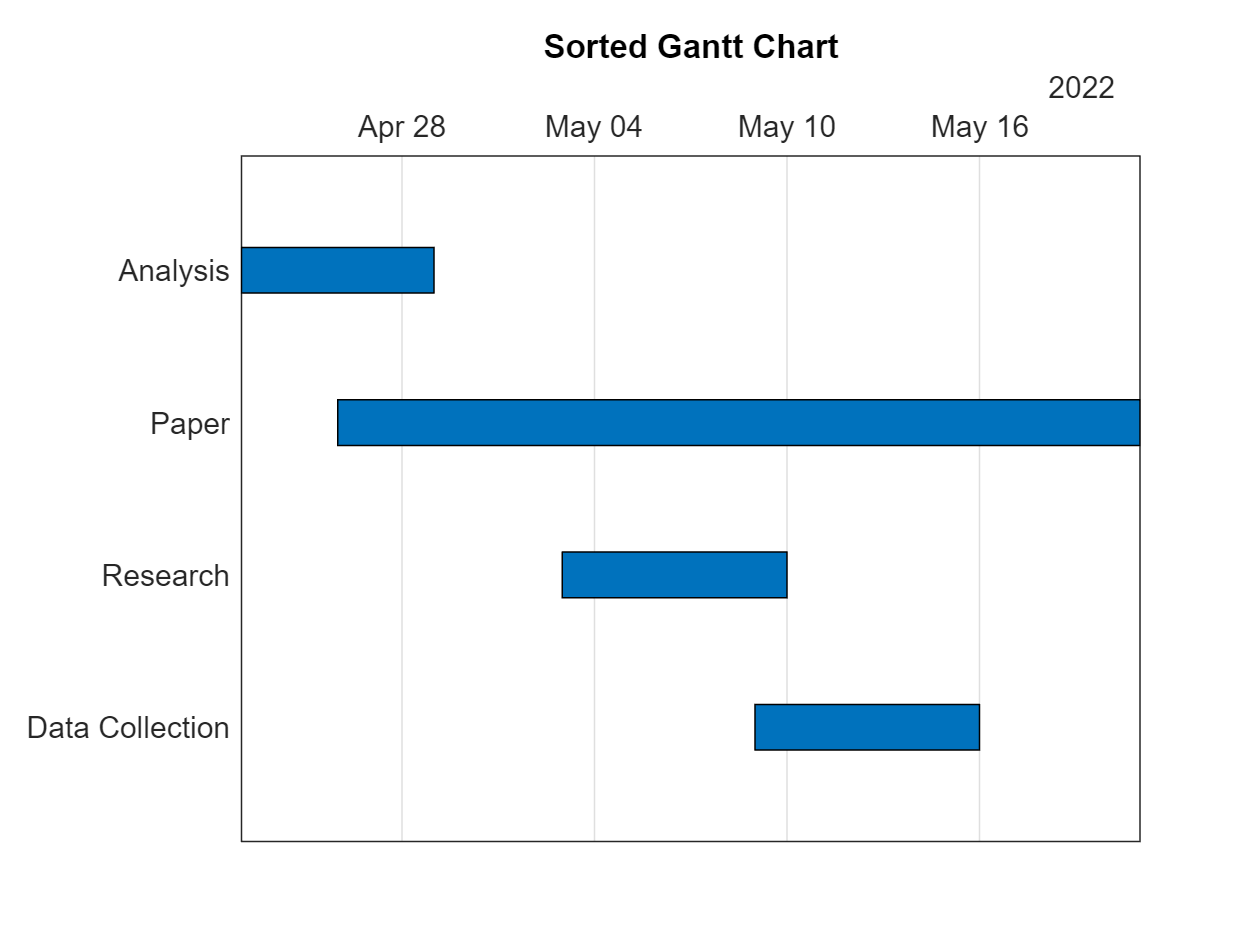

sort(j);
j.Title = "Sorted Gantt Chart";

New tasks can be added using the *addTask* method. The task will then be appended at the bottom of the chart. Let's add a new task to the latest end date of our tasks.

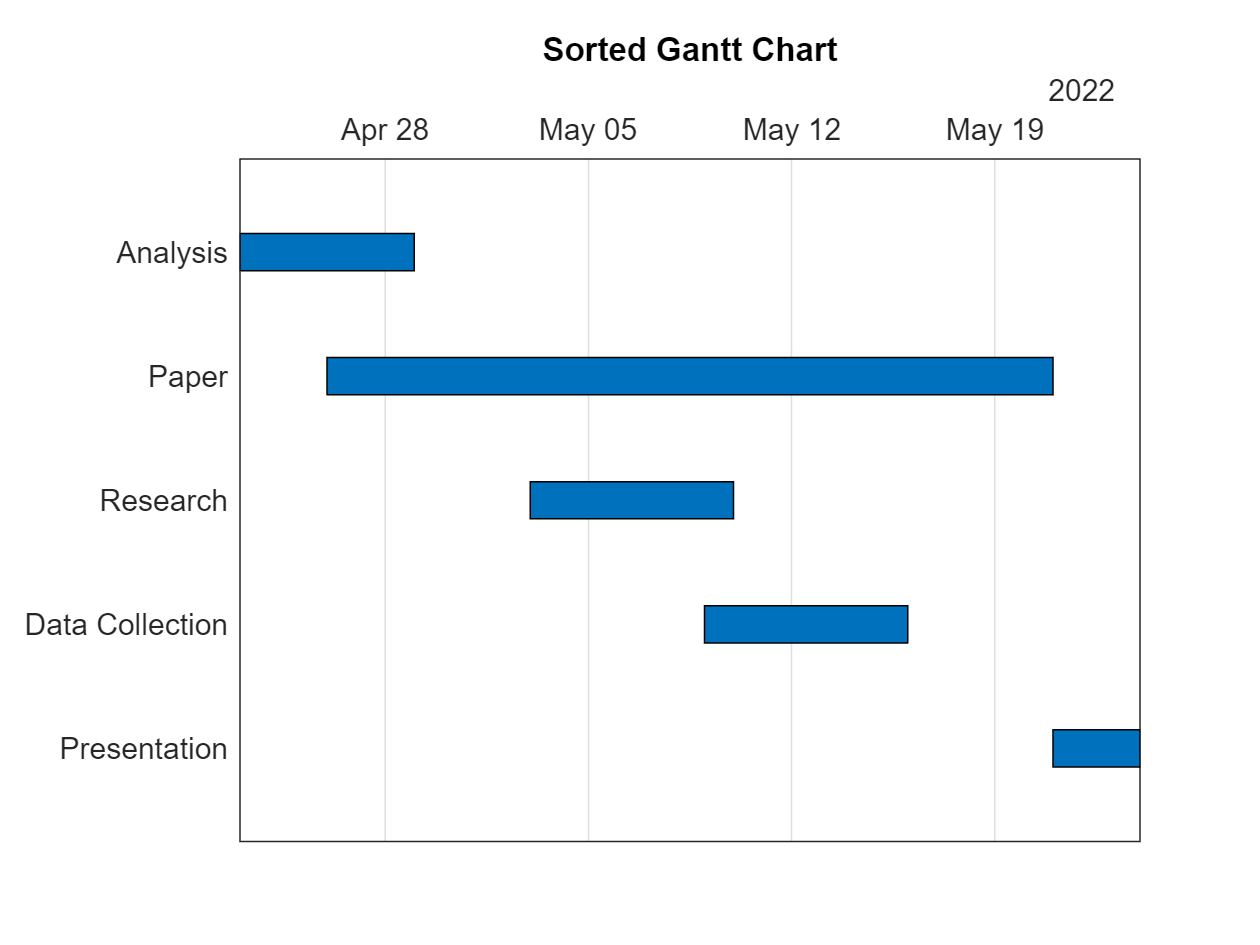

endDate = j.StartDate + j.DurationData;
latestEndDate = max(endDate);
addTask(j, "Presentation", days(3), latestEndDate);

Finally, if you'd like two tasks to be staggered such that neither task is overlapping, call the *stagger* method. Note that all this will change the start and end dates as needed while maintaining the duration, and update the object. Note that if two tasks in *TaskData* have the same name, this method will only stagger the first matching task.

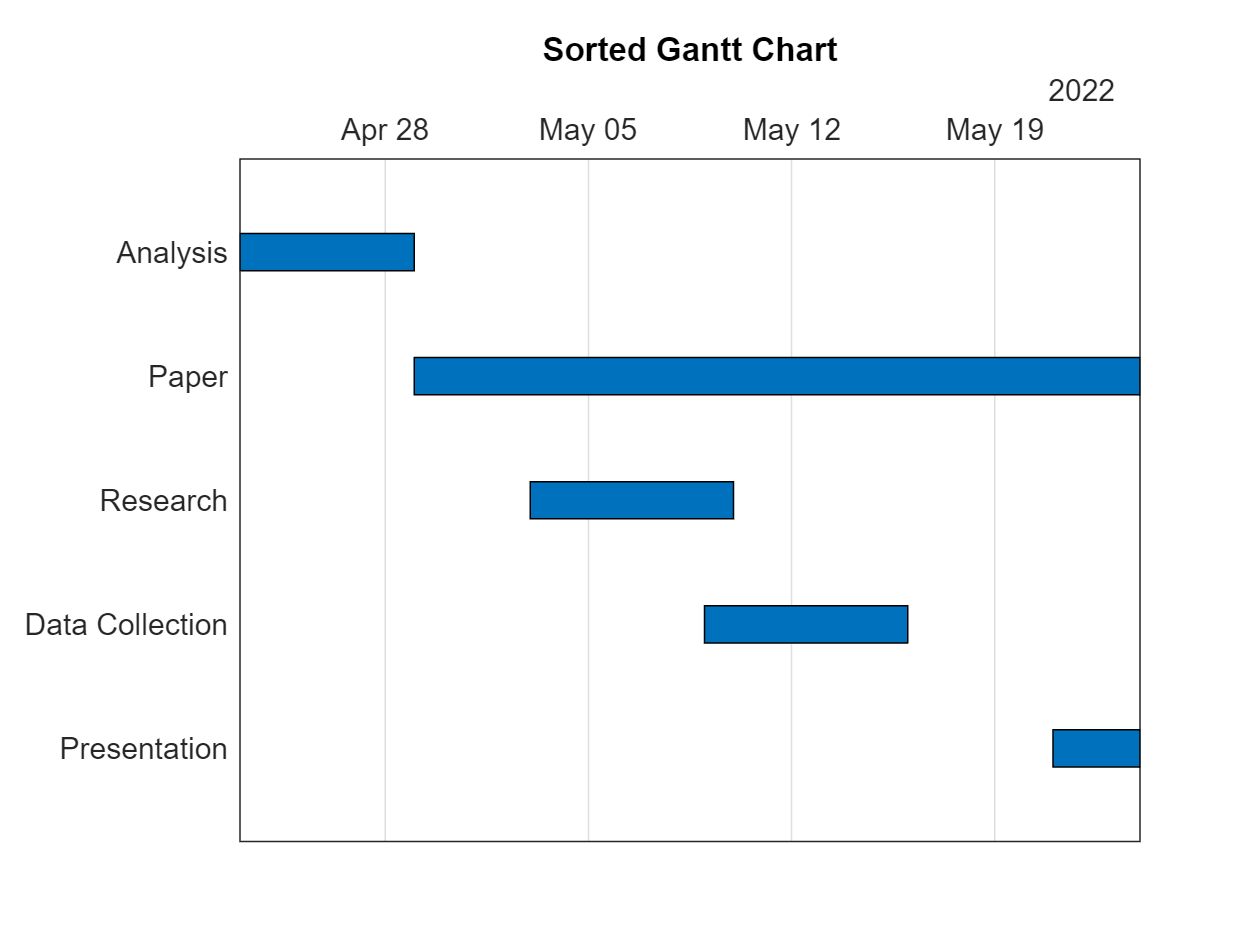

stagger(j, "Analysis", "Paper")